clear all
close all;
clc;
load('ECP_values.mat')
load('test1.mat','u','C','meas_fault')
load('Q6.mat','var_r0','G_y1_d','G_y2_d','G_y3_d')

% Physical system parameters
J_1 = 0.0025;                   % Disk 1 inertia kgm^2
J_2 = 0.0018;                   % Disk 2 inertia kgm^2
J_3 = 0.0018;                   % Disk 3 inertia kgm^2
k_1 = 2.7;                      % Shaft 1-2 stiffness Nm/rad
k_2 = 2.6;                      % Shaft 2-3 stiffness Nm/rad
b_1 = 0.0029;                   % Disk 1 damping and friction Nms/rad
b_2 = 0.0002;                   % Disk 2 damping and friction Nms/rad
b_3 = 0.00015;                  % Disk 3 damping and friction Nms/rad
T_Cp = ECP_values(12);          % Disk 1 Coulomb friction in positive direction
T_Cm = ECP_values(13);          % Disk 1 Coulomb friction in negative direction
atan_scale = 100;               % Sign approximation factor
w_th = 0.75;                    % Threshold angular velocity rad/s
wn=1;                           %natural frequency
zeta=0.96; 
%Simulation parameters:

T_s = 0.004;                           % Sampling period
f_m = 0.5;                              % Sensor fault vector (added to [y1;y2;y3])
f_m_time = 5;                         % Sensor fault occurence time

% The system states are [theta_1;omega_1;theta_2;omega_2;theta_3;omega_3]
x_0 = [0;0;0;0;0;0];                  % Initial conditions

simTime = 15;                         % Simulation duration in seconds

C = [ 1 0 0 0 0 0;
      0 0 1 0 0 0;
      0 0 0 0 1 0];


%Sensor meassurement noise parameters:

sigma_1=10^(-2);        %Uncorrelated noise of y1
sigma_2=10^(-2);        %Uncorrelated noise of y2
sigma_3=10^(-2);        %Uncorrelated noise of y3
P_F=0.01;
P_M=0.01;
P_D=1-P_M;
f_2=-0.025;
mu_1=f_2*(-5.3);
mu_0=0;
% sigma=sqrt(var_r0); %which value????
sigma=0.07;
syms hs lambs Ms x
h=0.5*chi2inv(0.99,1)

h = 3.3174

lambdas=0:0.0001:25;
y=ncx2cdf(2*h,1,lambdas);
[~,I]=min(abs(P_M*ones(size(lambdas))-y));
lambda=lambdas(I)

lambda = 24.0313

M=ceil((lambda*sigma^2)/((mu_1-mu_0)^2));    
A_init=zeros(M,1);


% reshape(sims.H_cusum.signals.values,1,size(sims.H_cusum.signals.values,3))
sims=sim('Lab7')

sims =   Simulink.SimulationOutput:

                  H_GLR: [1x1 struct] 
                   f_y2: [1x1 struct] 
                  g_GLR: [1x1 struct] 
                      r: [1x1 struct] 
                   tout: [3831x1 double] 
                      y: [1x1 struct] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


fig=figure

fig =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


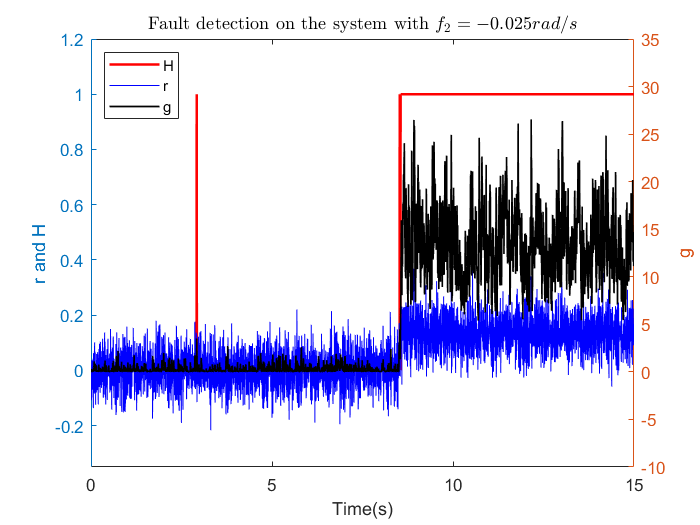

yyaxis left
plot(sims.H_GLR.time,sims.H_GLR.signals.values,'r','LineWidth',1.5)
hold on 
plot(sims.r.time,sims.r.signals.values,'b-')
ylim([-0.35 1.2])
ylabel('r and H')
hold on
yyaxis right
plot(sims.g_GLR.time,sims.g_GLR.signals.values,'k','LineWidth',1)

ylim([-10 35])
ylabel('g')
title('Fault detection on the system with $f_2=-0.025 rad/s$','Interpreter','latex')

xlabel('Time(s)')
legend('H','r','g','Location','northwest')
saveas(fig,'GLR.png')